clc; clear

# Encripción de Palabras Usando Matrices y Asignación del Abecedario a Números Reales.

#### Parte 1: Encripción.

Primero, es importante saber que una matriz es una transformación lineal, y en este caso, utilizamos una matriz clave que se ve de la siguiente forma:


$$A =   \pmatrix{2 & 3 \cr 3 & 5}$$


Siendo 2 y 5 números que multiplicados dan la fecha del día de hoy, 10 de agosto. Para completar la otra diagonal, es necesario saber que el determinante de la matriz será 1 o -1, esto debido a que si diera otro valor, al hacer la multiplicación de matrices con nuestros valores numéricos asignados a letras, pudiera darnos un resultado con decimales, lo cual complicaría la desencripción de los datos. Por consiguiente, 3 y 3 multiplicados dan 9, y al hacer la resta de 10 - 9 obtenemos 1.

Cabe aclarar que en algunas ocasiones, se debe usar el residuo del producto punto, esto para evitar que obtengamos un número mayor al de letras en el abecedario, así, aplicamos un concepto en el que nos imaginamos un reloj, en donde cada hora toma el valor de cada letra del abecedario y eventualmente los números se extrapolan y cada letra puede tener varios valores numéricos.

Usando la siguiente tabla, podemos asignar los valores iniciales:

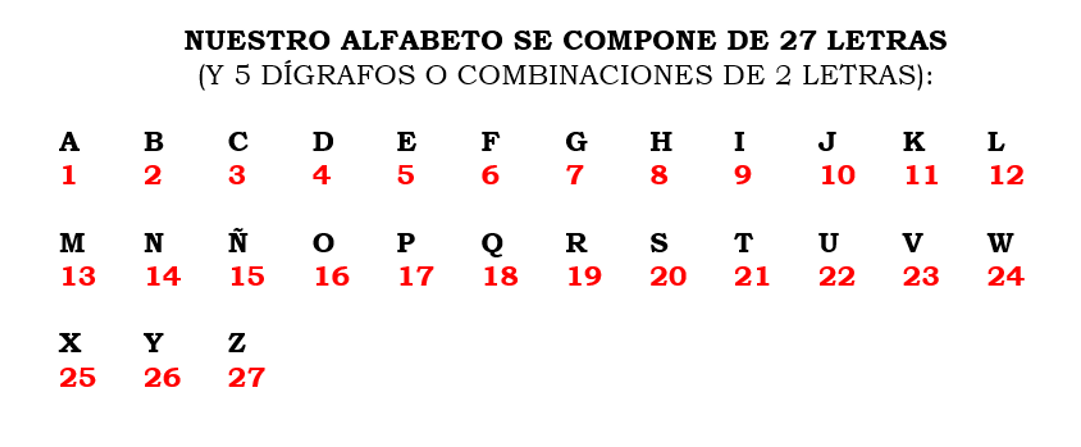

Y luego agrupando en matrices de 2x1 (así evitamos la confusión de saber si el valor de alguna letra está compuesta de uno o más valores numéricos, por ejemplo, tenemos el código 41149512, viendo esto, no sabemos si la segunda letra es 1 o 11, para ello, usamos matrices). 

Para la encripción usaremos mi nombre, Daniel, el cual se parte en tres, por lo que nuestra primer letra es 4, la segunda es 1, la tercera es 14, la cuarta es 9, la quinta es 5, y la sexta es 12 y obtenemos lo siguiente:


$$B=   \pmatrix{4 \cr 1}$$
 
$$C=   \pmatrix{14 \cr 9}$$
 
$$D=   \pmatrix{5 \cr 12}$$


Usando el proceso descrito anteriormente, obtenemos nuestras matrices de encripción y por último, sustituimos los valores numéricos por letras con la tabla anterior. 

Nota: En caso de encontrar algún 0, usaremos el valor para Z.

A=[2 3;3 5] % Matriz A (clave)

A =      2     3
     3     5


B=A*[4;1]; % Matriz B
B=mod(B, 27)

B =     11
    17


C=A*[14;9]; % Matriz C
C=mod(C, 27)

C =      1
     6


D=A*[5;12]; % Matriz D
D=mod(D, 27)

D =     19
    21


Y obtenemos el código: KPAFRT

#### Parte 2: Desencripción.

Usando el mismo sistema que la parte 1, volveremos a encriptar el código. A diferencia de la parte incial, usaremos la matriz inversa de nuestra clave, el demás procedimiento es el mismo.

Para este ejemplo, trabajaremos con el código: UYWATEUN

Primero lo acomodamos en matrices asignando el valor numérico de cada letra.


$$E=   \pmatrix{22 \cr 26}$$
 
$$F=   \pmatrix{24\cr 1}$$
 
$$G=   \pmatrix{21 \cr 5}$$
 
$$H=   \pmatrix{22 \cr 14}$$


A1=inv(A) % Matriz A1 (clave inversa)

A1 =      5    -3
    -3     2


E=A1*[22;26]; % Matriz E
E=mod(E, 27)

E =      5
    13


F=A1*[24;1]; % Matriz F
F=mod(F, 27)

F =      9
    11


G=A1*[21;5]; % Matriz G
G=mod(G, 27)

G =      9
     1


H=A1*[22;14]; % Matriz H
H=mod(H, 27)

H =     14
    16


Por último, buscamos el valor de cada letra con nuestros valores obtenidos y obtenemos el nombre: EMIKIANO

Nota: Al parecer al momento de que mi compañero hizo su encripción, confundió el valor numérico de la L por el de la K, resultando en otra palabra en su desencripción.

#### Reflexión:

    La principal diferencia entre una matriz y un vector es su forma de acceso, para un vector solo se utiliza un subíndice y para una matriz, dos subíndices, esto porque tienen una forma de m x n y como mencioné anteriormente,  una matriz es una transformación lineal por lo que es útil para este tipo de encripciones, igualmente existen muchas más aplicaiones, como el moviemiento dentro de videojuegos, ray tracing y demás, igualmente pueden describir movimientos complejos de partículas y una infinidad de cosas más, por lo que considero que es algo demasiado útil en el campo de la ingeniería.